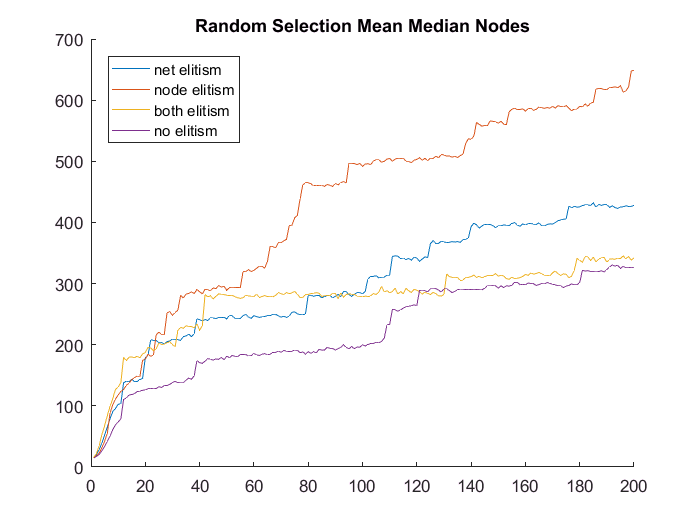

clear;
addpath('simulator');
p(1).topology = [6 2 1];
evaluationFunction = 'twoPoleEvaluation';
p(1).permutationOption = 1;
p(1).elitismOption = 1;
p(1).targetFitness = 1000;
p(1).maximumGenerations = 2500;

p(2) = p(1);
p(2).permutationOption = 1;
p(2).elitismOption = 2;

p(3) = p(1);
p(3).permutationOption = 1;
p(3).elitismOption = 3;

p(4) = p(1);
p(4).permutationOption = 1;
p(4).elitismOption = 4;

p(5) = p(1);
p(5).permutationOption = 2;
p(5).elitismOption = 1;

p(6) = p(1);
p(6).permutationOption = 2;
p(6).elitismOption = 2;

p(7) = p(1);
p(7).permutationOption = 2;
p(7).elitismOption = 3;

p(8) = p(1);
p(8).permutationOption = 2;
p(8).elitismOption = 4;

nRuns = 30;

for experiment=1:8
  clearvars medianNodes bestNet medianNet r;
  medianNodes = ones(nRuns,p(experiment).maximumGenerations) * p(experiment).targetFitness; 
  bestNet = ones(nRuns,p(experiment).maximumGenerations) * p(experiment).targetFitness;
  medianNet = ones(nRuns,p(experiment).maximumGenerations) * p(experiment).targetFitness;
  for run=1:nRuns
    r(run) = doEsp(evaluationFunction, p(experiment));
    medianNodes(run,1:size(r(run).medianNodeFitness,2)) = mean(r(run).medianNodeFitness,1);
    bestNet(run,1:size(r(run).bestNetFitness,2)) = r(run).bestNetFitness;
    medianNet(run,1:size(r(run).medianNetFitness,2)) = r(run).medianNetFitness;

  end
  meanMedianNodes(experiment,:) = mean(medianNodes,1);
  meanBestNet(experiment,:) = mean(bestNet,1);
  meanMedianNet(experiment,:) = mean(medianNet,1);
end

figure(1); clf; hold on;
for i=1:4  
  plot(meanMedianNodes(i,:));
end
legend('net elitism','node elitism',...
  'both elitism', 'no elitism',...
  'Location','northwest');
title('Random Selection Mean Median Nodes');

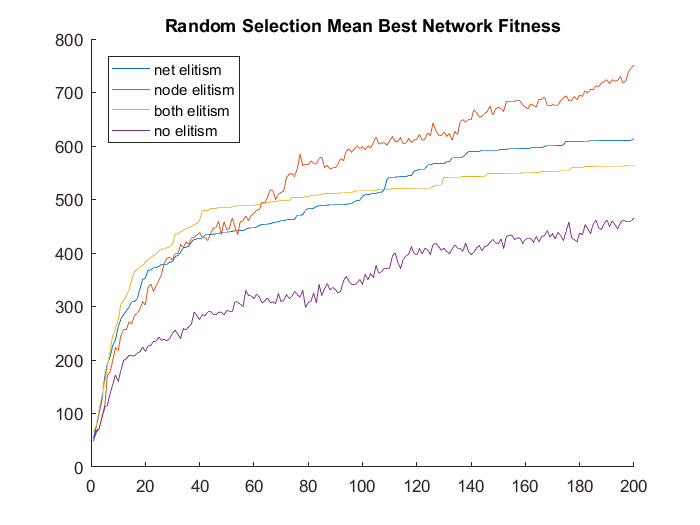

ylabel('Endured timesteps');
xlabel('Generations');

figure(2); clf; hold on;
for i=1:4  
  plot(meanBestNet(i,:));
end
legend('net elitism','node elitism',...
  'both elitism', 'no elitism',...
  'Location','northwest');
title('Random Selection Mean Best Network Fitness');

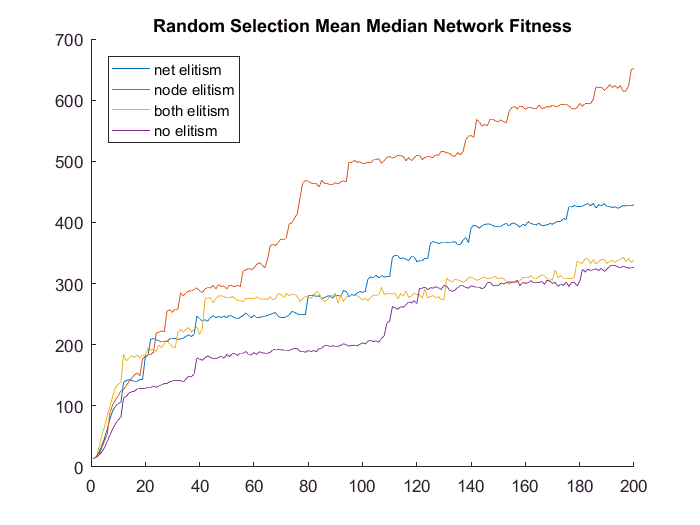

ylabel('Endured timesteps');
xlabel('Generations');

figure(3); clf; hold on;
for i=1:4  
  plot(meanMedianNet(i,:));
end
legend('net elitism','node elitism',...
  'both elitism', 'no elitism',...
  'Location','northwest');
title('Random Selection Mean Median Network Fitness');

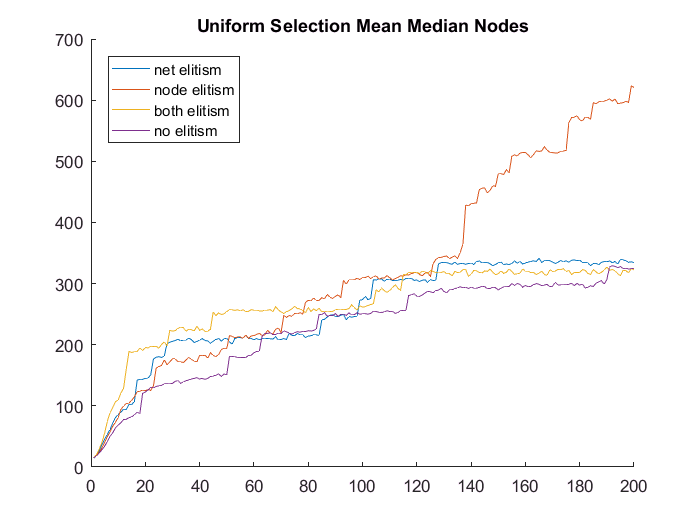

ylabel('Endured timesteps');
xlabel('Generations');

figure(4); clf; hold on;
for i=5:8  
  plot(meanMedianNodes(i,:));
end
legend('net elitism','node elitism',...
  'both elitism', 'no elitism',...
  'Location','northwest');
title('Uniform Selection Mean Median Nodes');

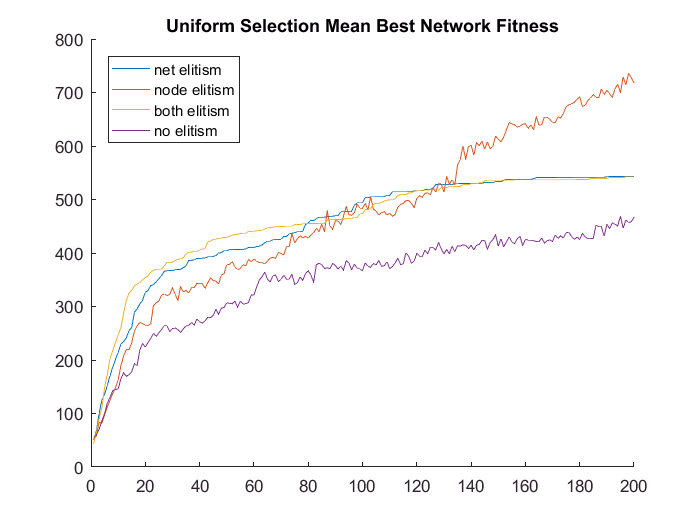

ylabel('Endured timesteps');
xlabel('Generations');

figure(5); clf; hold on;
for i=5:8  
  plot(meanBestNet(i,:));
end
legend('net elitism','node elitism',...
  'both elitism', 'no elitism',...
  'Location','northwest');
title('Uniform Selection Mean Best Network Fitness');

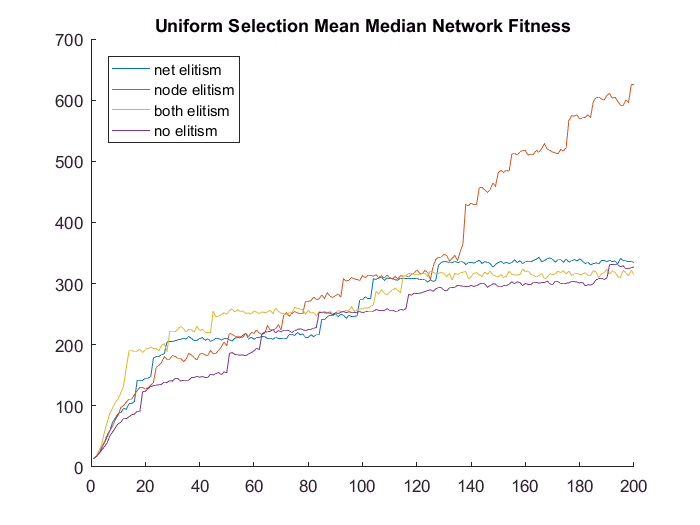

ylabel('Endured timesteps');
xlabel('Generations');

figure(6); clf; hold on;
for i=5:8  
  plot(meanMedianNet(i,:));
end
legend('net elitism','node elitism',...
  'both elitism', 'no elitism',...
  'Location','northwest');
title('Uniform Selection Mean Median Network Fitness');

ylabel('Endured timesteps');
xlabel('Generations');

figure(7); clf; hold on;
plot(meanMedianNet(1,:));
plot(meanMedianNet(2,:));
plot(meanMedianNet(5,:));
plot(meanMedianNet(6,:));
legend('random net','random node',...
  'uniform net', 'uniform node',...
  'Location','northwest');
title('Mean Median Network Fitness');
ylabel('Endured timesteps');
xlabel('Generations');